## MFPT Deterministic / Results

**Purpose1:** Compute FPTs for an assortment of Deterministic Models

**Purpose2:** Plot & Compare MFPTs of Deterministic & Stochastic Models

**Method: **ode45 & searching through time indecies for FPT. 

**Run Time: **Seconds

**Needed Imports:** mfptVals from mfpt.mlx workspace

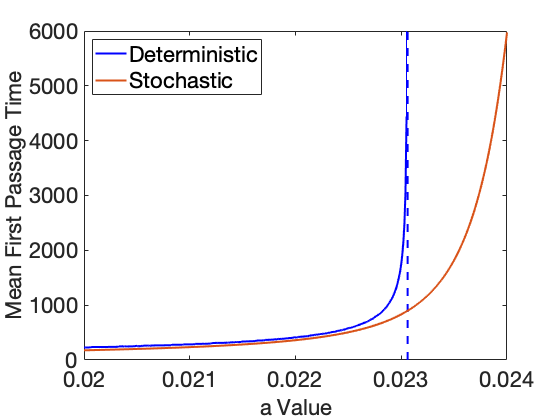

global a; 
global i;

% Assortment of a & fpt values
a = linspace(.02,.02305, 305);
fpt = zeros(1,305);

%Fixed Params for DEs
x0 = .03;
tmax = 5000;

%Sim DEs & Get FPTs
for i = 1:length(a)
    
    [t,y] = ode45(@DE,[0 tmax],x0, odeset('RelTol',1e-10));
    
    %Get FPTS
    for j = 1: length(y)
        
        if(y(j) > barriers(i))
            
            fpt(i) = t(j);
            break;
        end
        
    end
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Plotting Deterministic Data
plot(a,fpt,'Color','blue','DisplayName','Deterministic','LineWidth',2)
h = line([.02305 .02305],[4439.591 6000],'linestyle','-','Color','blue','DisplayName','Deterministic');
h.Annotation.LegendInformation.IconDisplayStyle = 'off';

%Plot Asymptote
asym = line([.02306 .02306],[0 6000],'linestyle','--','Color','blue','LineWidth',2);
asym.Annotation.LegendInformation.IconDisplayStyle = 'off';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Plotting Stochastic Data
a = linspace(.02, .024, 400);
hold on;

plot(a,mfptVals,'DisplayName','Stochastic','LineWidth',2)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Modifications
lgd = legend;
lgd.Location = 'northwest';
lgd.FontSize = 22;
set(gca,'FontSize',22);
xlim([.02 .024])
xlabel('a Value','FontSize',22);
ylabel('Mean First Passage Time','FontSize',22);

**Our Differential Equation**

function f = DE(t,x)

global a;
global i;

%Parameters
r = .05;
K = 2;
h = .38;
q = 5;

f = r * x * (1-(x/K)) - (a(i)*x^(q))/(x^(q) + h^(q));

end